C_O = load('ConcValues/run2/C_O_19e-2fM_32_600_75_runs100.mat').C_O;
x_in = load('ConcValues/run2/x_in_19e-2fM_32_600_75_runs100.mat').x_in;

thresh1 = mean(C_O);

maxCO = max(C_O);
minCO = 1;

for i=1:size(C_O,1)
    if(C_O(i,1)~=0)
        if(C_O(i,1)<minCO)
            minCO = C_O(i,1);
        end
    end
end

thresh2 = (minCO + maxCO)/2;

thresh3 = 1e-20;

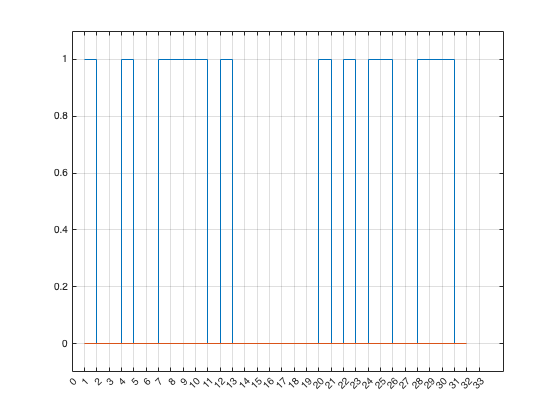

x_out1 = zeros(size(x_in));
for j=1:size(C_O,1)
    if(C_O(j,1)>thresh1)
        x_out1(1,j) = 1;
    end
end

x_out2 = zeros(size(x_in));
for j=1:size(C_O,1)
    if(C_O(j,1)>thresh2)
        x_out2(1,j) = 1;
    end
end

x_out3 = zeros(size(x_in));
for j=1:size(C_O,1)
    if(C_O(j,1)>thresh3)
        x_out3(1,j) = 1;
    end
end

figure()
stairs(x_in);
hold on;
stairs(x_out1);
xticks(0:size(x_in,2)+1)
grid on;
ylim([-0.1 1.1])


be1 = xor(x_in,x_out1);
bec1 = sum(be1(:)==1);
ber1 = bec1/size(x_in,2);

be2 = xor(x_in,x_out2);
bec2 = sum(be2(:)==1);
ber2 = bec2/size(x_in,2);

be3 = xor(x_in,x_out3);
bec3 = sum(be3(:)==1);
ber3 = bec3/size(x_in,2);

